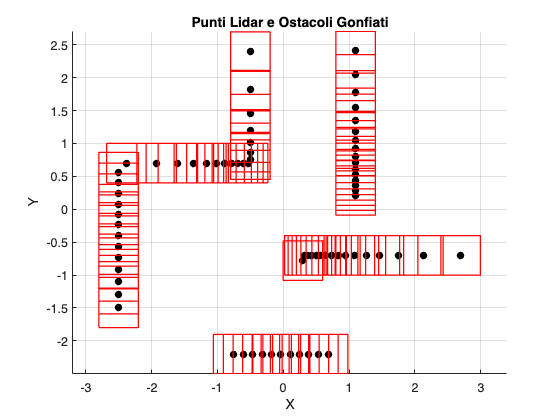

% Script per testare la funzione lidar_to_obstacles
% Dati Lidar di esempio
lidar_data = Drone.Drone_3.Lidar.scan_points_new;
% Distanza per gonfiare i quadrati
buffer_distance = 0.6;

% Trova gli ostacoli usando i dati lidar
obstacles = lidar_to_obstacles(lidar_data, buffer_distance);

% Plotta i punti lidar e gli ostacoli trovati
plot_obstacles(lidar_data, obstacles);

function obstacles = lidar_to_obstacles(lidar_data, buffer_distance)
    % Inizializza la matrice per gli ostacoli
    num_points = size(lidar_data, 1);
    obstacles = zeros(num_points, 4); % Ogni riga conterrà le coordinate di due punti (basso sinistra e alto destro)

    % Calcola il buffer quadrato attorno a ciascun punto
    for i = 1:num_points
        point = lidar_data(i, :);
        square = calculate_square(point, buffer_distance);
        obstacles(i, :) = square; % Salva le coordinate dei due punti
    end
end

function square = calculate_square(point, buffer_distance)
    % Calcola le coordinate del quadrato attorno al punto
    x = point(1);
    y = point(2);
    half_side = buffer_distance / 2;

    % Calcola i punti basso sinistra e alto destro del quadrato
    bottom_left = [x - half_side, y - half_side];
    top_right = [x + half_side, y + half_side];

    % Salva le coordinate dei due punti
    square = [bottom_left, top_right];
end

function plot_obstacles(lidar_data, obstacles)
    figure;
    hold on;

    % Plotta i punti Lidar
    scatter(lidar_data(:, 1), lidar_data(:, 2), 'k', 'filled');

    % Plotta gli ostacoli come quadrati
    num_obstacles = size(obstacles, 1);
    for i = 1:num_obstacles
        % Estrai le coordinate dei due punti per l'ostacolo
        bottom_left = obstacles(i, 1:2);
        top_right = obstacles(i, 3:4);

        % Calcola gli altri vertici del quadrato
        bottom_right = [top_right(1), bottom_left(2)];
        top_left = [bottom_left(1), top_right(2)];

        % Plotta il quadrato
        square_vertices = [bottom_left; bottom_right; top_right; top_left; bottom_left];
        plot(square_vertices(:, 1), square_vertices(:, 2), 'r', 'LineWidth', 1);
    end

    hold off;
    axis equal;
    xlabel('X');
    ylabel('Y');
    title('Punti Lidar e Ostacoli Gonfiati');
    grid on;
end

